# Problem 4.3.4

% Define equation
syms F(x);
F(x) = 1/x^2 - sin(x);

x0 = [1.5,2,3.2,4,5,2*pi];

% Solve system using Newton's method for multiple intial guesses
for x = x0
    soln = newton(F,x);
    
    fprintf('When x_0 = %f, Newtons solution is x = %f\n\n',x,soln)
end

When x_0 = 1.500000, Newtons solution is x = 1.068224

When x_0 = 2.000000, Newtons solution is x = 6.308317

When x_0 = 3.200000, Newtons solution is x = 3.032645

When x_0 = 4.000000, Newtons solution is x = 3.032645

When x_0 = 5.000000, Newtons solution is x = 9.413493

When x_0 = 6.283185, Newtons solution is x = 6.308317



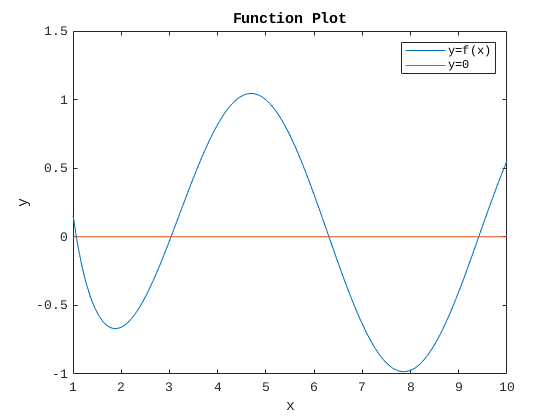

% Visually verify solutions
x = linspace(1,10,100);
plot(x,F(x),x,x ./ x - 1)
title('Function Plot')
xlabel('x')
ylabel('y')
legend('y=f(x)','y=0')

From the numerous solutions above, we can see that the choice initial guess really matters in which solution we will recover. Because Newton's method is based on the tangent line approximation, the root found is not necessarily the one that is closest to the guess. The plot above shows that an initial guess could be carried far away by the tangent line. Even worse, if our initial guess was at any of the minima or maxima of $f(x)$, Newton's method becomes undefined and we can't find a solution.

# Problem 4.5.2

Suppose $f(x) = Ax - b$ for $n\times n$ matrix $A$ and constant $n\times 1$ vector $b$. Then, $Ax-b$ has a root at $x = A\backslash b$.

Now, let's use Newton's method to find our root. First, we need to compute the Jacobian of $f$:

$jac(f) = \pmatrix{A_{11} & A_{12} & \cdots & A_{1n} \cr A_{21} & A_{22} & \cdots & A_{2n} \cr \vdots & \vdots & \ddots & \vdots \cr A_{n1} & A_{n2} & \cdots & A_{nn}} = A$.

Then, if we have an initial guess of $x_0$, the solution after one iteration of Newton's method is given by


$$x = x_0 - jac(f(x_0)) \backslash f(x_0)$$


   
$$= x_0 - A \backslash (Ax_0 - b)$$


   
$$= x_0 - \underset{I}{\underbrace{A \backslash A}} x_0 - A \backslash b$$


   
$$= x_0 - x_0 + A \backslash b$$
 

   $= A \backslash b$.

So, after one iteration of Newton's method, we recover the exact root to $Ax - b$.

function x0 = newton(F,x0)
    syms x;
    f = matlabFunction(F);
    df = matlabFunction(diff(F,x));
    
    % Convergence Settings
    epsilon = 10^(-15);
    maxIts = 50;
    its = 0;
    
    while (abs(f(x0)) > epsilon && its < maxIts) 
        x0 = x0 - f(x0)/df(x0);
        
        its = its + 1;
    end
end